**HW2 Program Assignment**

**By:105031247 張廷碩**

P1.

(a)

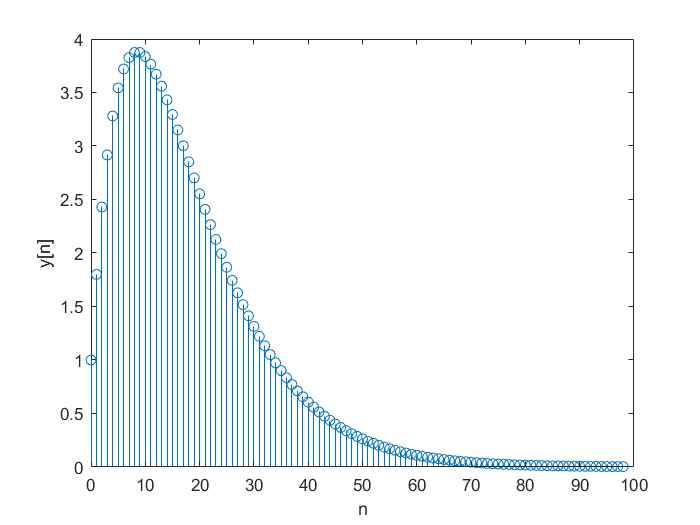

n=linspace(0,98,99);
Y(n+1)=(n+1).*0.9.^(n);
stem(n,Y)
xlabel('n')
ylabel('y[n]')

(b)

n=linspace(0,49,50);
x=0.9.^n;

x =     1.0000    0.9000    0.8100    0.7290    0.6561    0.5905    0.5314    0.4783    0.4305    0.3874    0.3487    0.3138    0.2824    0.2542    0.2288    0.2059    0.1853    0.1668    0.1501    0.1351    0.1216    0.1094    0.0985    0.0886    0.0798    0.0718    0.0646    0.0581    0.0523    0.0471    0.0424    0.0382    0.0343    0.0309    0.0278    0.0250    0.0225    0.0203    0.0182    0.0164    0.0148    0.0133    0.0120    0.0108    0.0097    0.0087    0.0079    0.0071    0.0064    0.0057


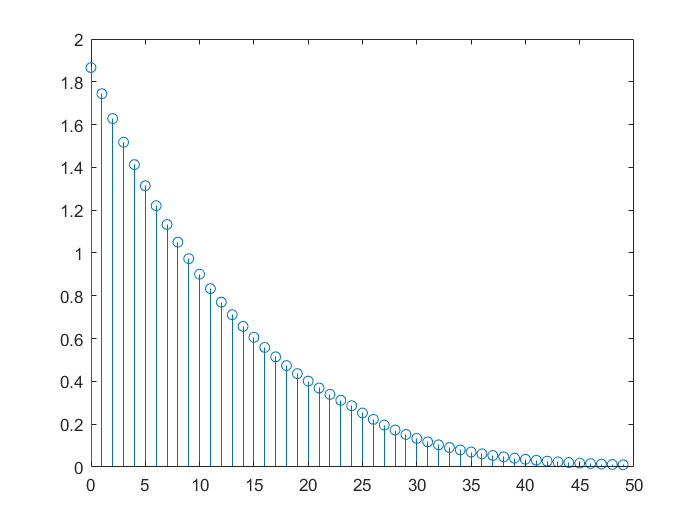

h=x;
y=conv(x,h,"same");
stem(n,y)

(c)

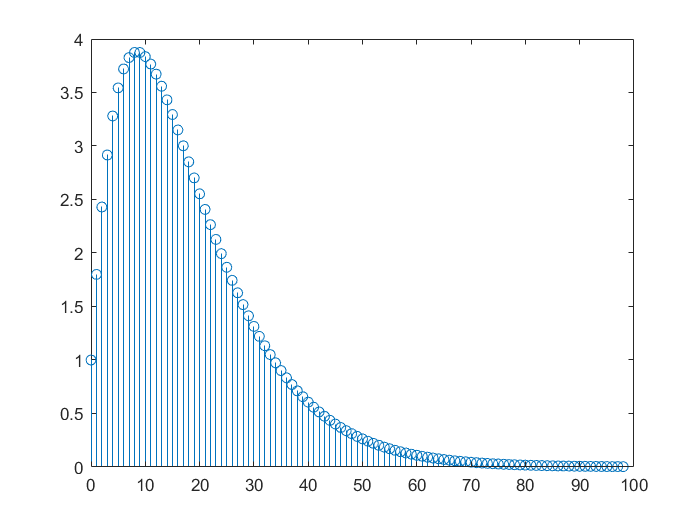

n=linspace(0,98,99);
x=0.9.^n;
h=x;
y=filter(x,1,h);
stem(n,y)

(d)

2.

(a)

(b)

n=0:100;
x=sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101);
h=ones(1,5);
y=conv(x,h,"same");
Y1=sum(y,"all")

Y1 = 2.3810

X=sum(x,"all");
H=sum(h,"all");
Y2=X*H

Y2 = 2.6043

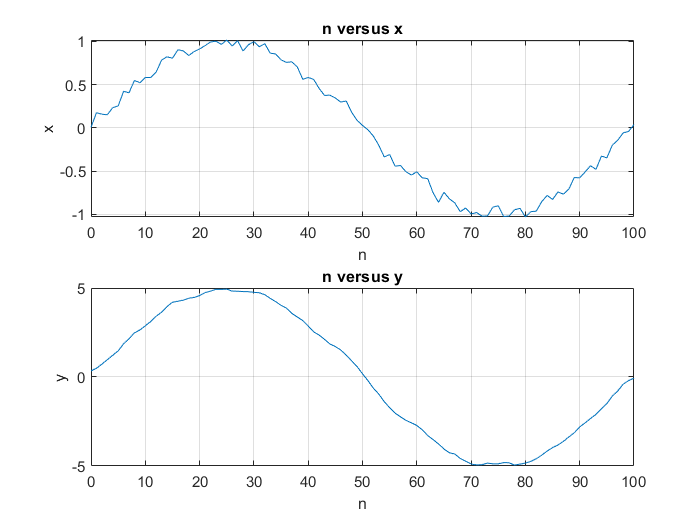

figure
subplot(2,1,1),plot(n,x);grid on;
xlabel('n') ; ylabel('x') ; title('n versus x')
subplot(2,1,2),plot(n,y);grid on;
xlabel('n') ; ylabel('y') ; title('n versus y')

(c)

h=[1/5 1/5 1/5 1/5 1/5];
Ah=sum(h,"all");
n=0:100;
x=sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101);
y=conv(x,h,"same");
Y3=sum(y,"all")

Y3 = -0.8669

X=sum(x,"all");
Y4=X*Ah

Y4 = -0.9049

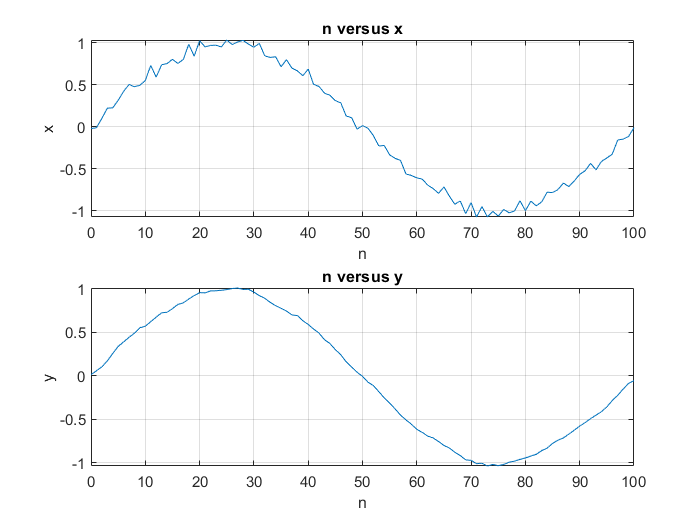

figure
subplot(2,1,1),plot(n,x);grid on;
xlabel('n') ; ylabel('x') ; title('n versus x')
subplot(2,1,2),plot(n,y);grid on;
xlabel('n') ; ylabel('y') ; title('n versus y')

(d)

3.

(a)

clc
b=[-6,6];
a=[-3,1];
[x,n]=delta(0,0,10);
y=filter(b,a,x)

y =     2.0000
   -1.3333
   -0.4444
   -0.1481
   -0.0494
   -0.0165
   -0.0055
   -0.0018
   -0.0006
   -0.0002


h=impz(b,a,100)

h =     2.0000
   -1.3333
   -0.4444
   -0.1481
   -0.0494
   -0.0165
   -0.0055
   -0.0018
   -0.0006
   -0.0002


(b)

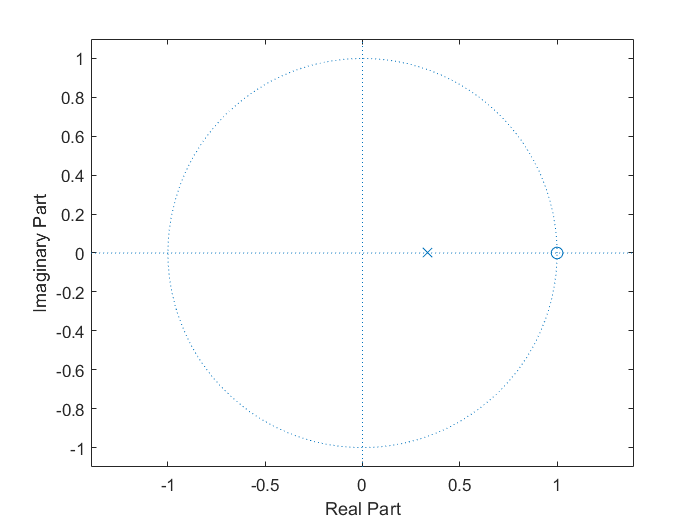

figure
zplane(b,a)

4.

(a)

(b)

5.

(a)

syms z A w;
y=iztrans(A*sin(w)/(1-2*cos(w)*z^(-1)+z^(-2)))

$$y = A\,\cos\left(n\,w\right)\,\sin\left(w\right)+A\,\sin\left(n\,w\right)\,\cos\left(w\right)$$

(b)

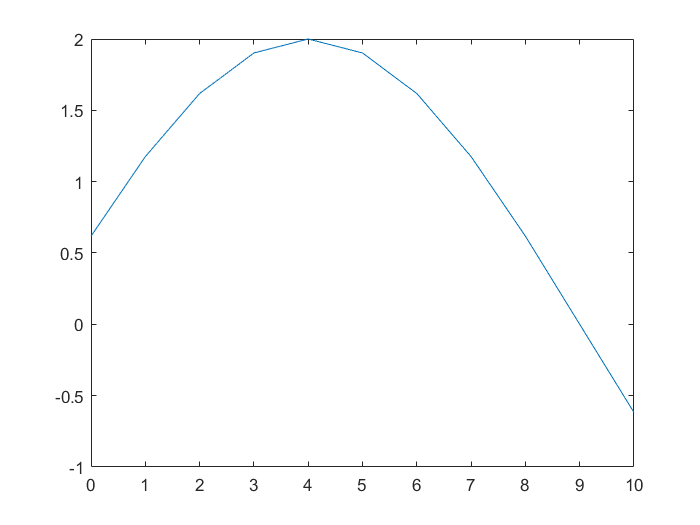

b=[0 0 0];
a=[1 -2*cos(0.1*pi) 1];
yic=[0 -2*sin(0.1*pi)];
xic=[0 0];
zic = filtic(b, a, yic, xic);
y = filter(b, a, x, zic);
plot(n,y)


$$$$


9.

img = imread('DSP.png');

Error using imread>get_full_filename (line 568)
File "DSP.png" does not exist.

Error in imread (line 377)
    fullname = get_full_filename(filename);

%imshow(img);
imwrite(img, 'DSP0.png');

(a)

p1=ones(5,5)/25;
imgg=double(img);
img2=conv2(imgg,p1,"full");
%imshow(img2);

(b)

h1=[1 0 -1;2 0 -2;1 0 -1];
h2=[1 2 1;0 0 0;-1 -2 -1];
a=conv2(h1,imgg,"full");
b=conv2(h2,imgg,"full");
A=uint8(a);
B=uint8(abs(b));
%imshow(A);
%imshow(B);

(c)

c=filter2(h1,imgg,"full");
d=filter2(h2,imgg,"full");
C=uint8(c);
D=uint8(abs(d));
%imshow(C);


10.

[y,Fs] = audioread('handel.wav');
playerObj = audioplayer(y, Fs);
play(playerObj);
%audiowrite('handel0.wav', y, Fs);

(a)

Ft=Fs/2;
playerObj = audioplayer(y, Ft);
%play(playerObj);

(b)

Fu=Ft/2;
%playerObj = audioplayer(y, Fu);


(c)